# The Poisson Equation

The Poisson equation 


$$\frac{\partial^2\phi}{\partial x^2} + \frac{\partial^2\phi}{\partial y^2} = f(x,y)$$


in two dimensional Cartesian coordinates can be solved using finite difference schemes as well. In this case we let 


$$f(x,y) = -8\pi^2\sin(2\pi x)\sin(2\pi y)$$


and solve the equation on a square grid from 0 to 1. Notice that these equations do not depend on time and so do not require us to step through the time evolution of the solution. We can therefore solve the finite difference scheme as a matrix equation, though we have to be careful to set up the matrices in the correct way. 

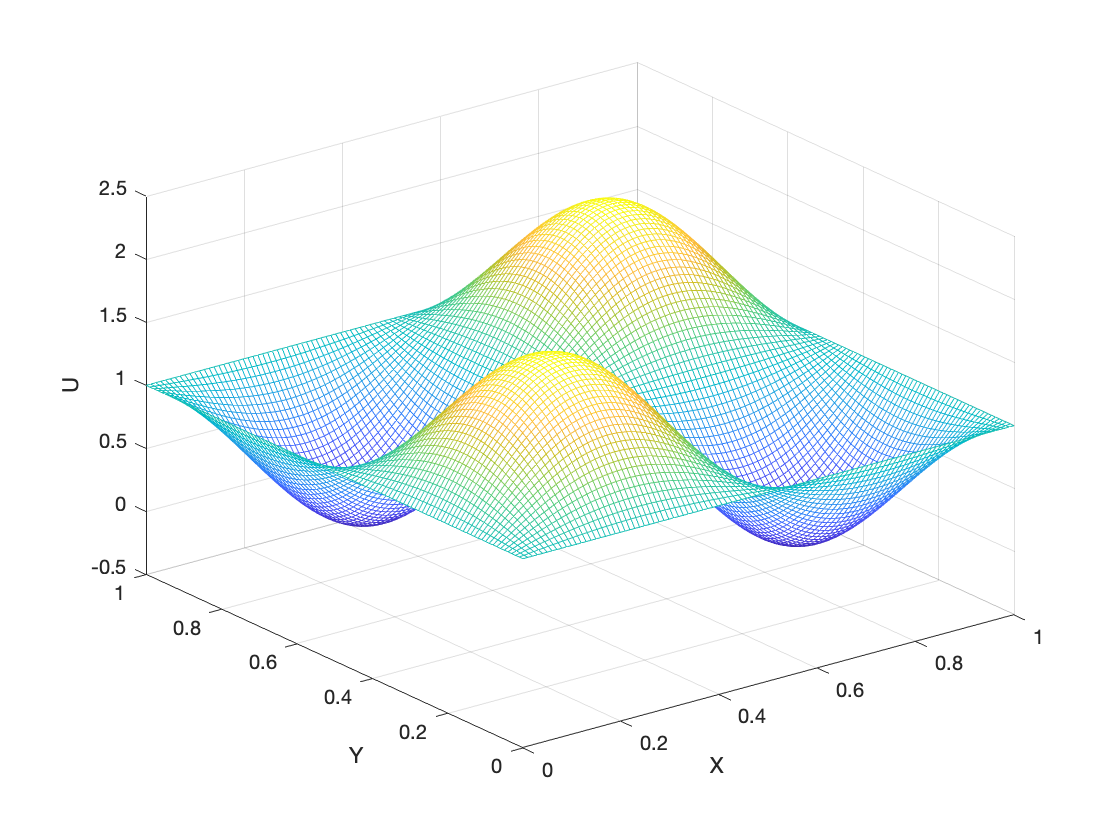

f_rhs = @(x,y) -8.0 * pi^2 * sin(2.0*pi*x).*sin(2.0*pi*y);

a = 0.0;
b = 1.0;

n_grid = 100;

[x, y, u_solution] = PoissonMMEES(f_rhs, a, b, n_grid);

figure
mesh(x, y, u_solution)
xlabel('X')
ylabel('Y')
zlabel('U')

***Exercise: ****Modify the solver for the Poisson equation to allow for non-constant boundary conditions by adding an additional function to the function call. *